%Joseph Dearing
function samples = directdisk(n_samples,N,sigma)
samples=zeros(N,n_samples);
c=0;
while c<n_samples
    x=zeros(1,N);
    y=zeros(1,N);
    valid=true;
    %creating positions for each disk
    for i =1:N
        x(i)=sigma+(1-2*sigma)*rand();
        y(i)=sigma+(1-2*sigma)*rand();
        %determining distance between each pair of disks
        for j=1:i-1
            d=sqrt((x(i)-x(j))^2+(y(i)-y(j))^2);
            if d < 2 * sigma
                %if disks to close update valid
                valid = false;
                break;
            end
        end
        if ~valid
            %if not valid we restart loop
            break;
        end
    end
        if valid
            %if valid record and increase count
            c=c+1;
            samples(:,c)=x;
        end       
end
samples=samples(:)';
end

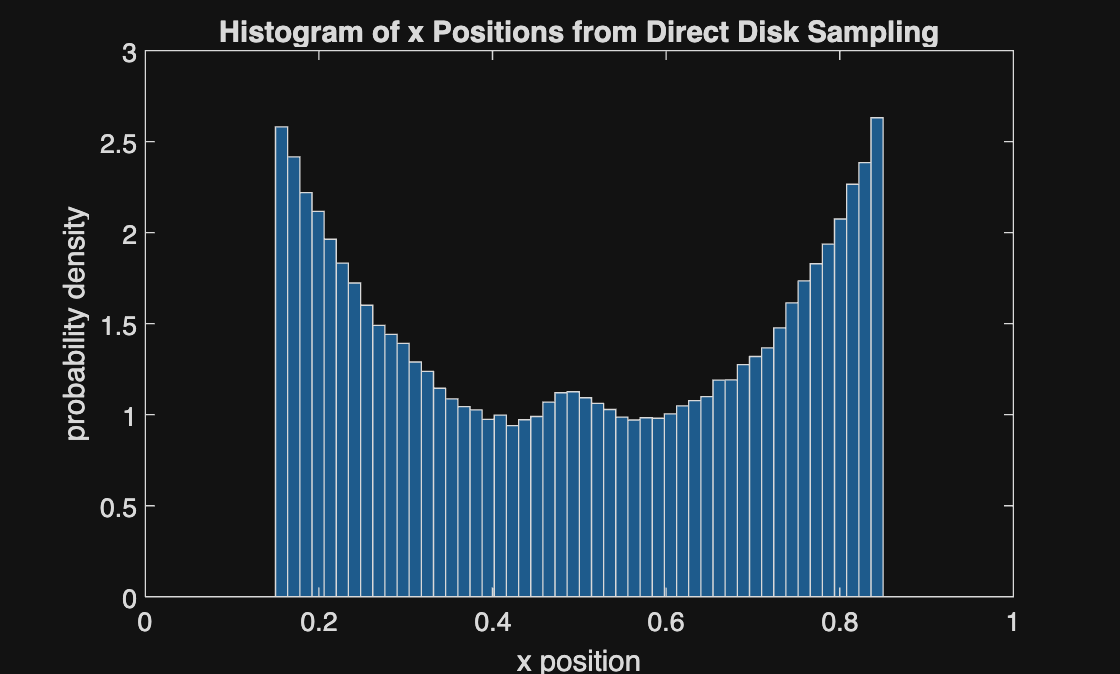

xpos=directdisk(50000,4,0.15);
histogram(xpos,"Numbins",50,"Normalization","pdf")
xlim([0,1])
xlabel('x position')
ylabel('probability density')
title('Histogram of x Positions from Direct Disk Sampling');

We can see that the direct-disk algorithm gives the same batman figure. Both algorithms sample the distribution of the same system. Direct disks does so through independant samples whilst event disks does it through correlated samples. Both of which converge to the same stationary distribution. Any devitions should be due to noise or insufficient sampling.

function samples=markovdisks(pos,N,sigma,n_samples,delta)
samples=zeros(N,n_samples);
for i = 1:n_samples
    k=randi(N);
    dx=delta*(2*rand()-1);
    dy=delta*(2*rand()-1);
    xtrial=pos(1,k)+dx;
    ytrial=pos(2,k)+dy;
    valid=true;
    %checking if inside box
    if xtrial<sigma || xtrial>1-sigma || ytrial<sigma || ytrial>1-sigma
        valid=false;
    end
    %checking for disk overlap
    if valid
        for j=1:N
            if j==k
                continue
            end
            d=(xtrial-pos(1,j))^2+(ytrial-pos(2,j))^2;
            if d<4*(sigma)^2
                %checking if disks overlap
                valid=false;
                break;
            end
        end
    end
    %unlike for direct, we record postion regardless
    %update postions if no overlap then record
    if valid
        pos(1,k)=xtrial;
        pos(2,k)=ytrial;
    end
    samples(:,i)=pos(1,:)';
end
samples=samples(:)';
end    

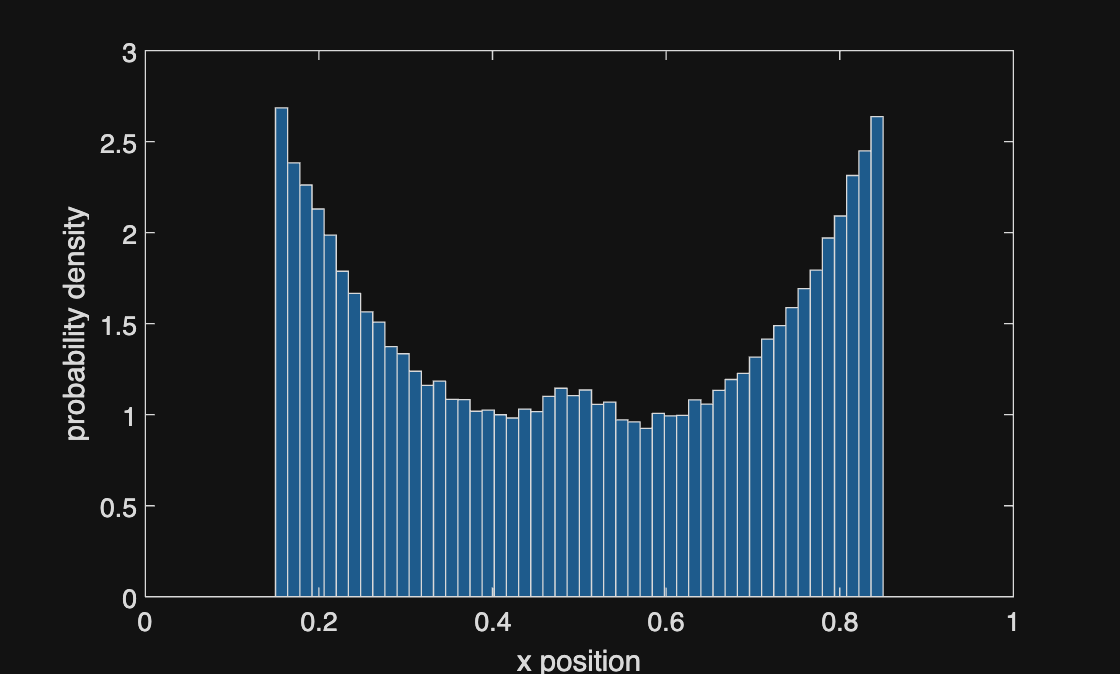

pos=[0.25,0.25,0.75,0.75;0.25,0.75,0.25,0.75];
xsamples=markovdisks(pos,4,0.15,500000,0.1);
histogram(xsamples,"NumBins",50,"Normalization","pdf")
xlabel('x position')
ylabel('probability density')
xlim([0,1]);

Again we see the batman figure. Furthermore, we again expect the output to be exactly the same up to some error or insufficient sampling due to the fact they sample the exact same distribution. Deviations will on occur due to such and not the fact N=4.